u_0 = [20e3; 0; 0; 0; 0; 0; 0];
options = odeset('MaxStep', 1)

options = struct with fields:
              AbsTol: []
                 BDF: []
              Events: []
         InitialStep: []
            Jacobian: []
           JConstant: []
            JPattern: []
                Mass: []
        MassSingular: []
            MaxOrder: []
             MaxStep: 1
         NonNegative: []
         NormControl: []
           OutputFcn: []
           OutputSel: []
              Refine: []
              RelTol: []
               Stats: []
          Vectorized: []
    MStateDependence: []
           MvPattern: []
        InitialSlope: []



[t, u] = ode45(@rocketModel, [0, 600], u_0, options)

t =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0001
    0.0001
    0.0001
    0.0002


u = 1.0e+04 *

    2.0000         0         0         0         0         0         0
    2.0000         0    0.0000         0    0.0000         0         0
    2.0000         0    0.0000         0    0.0000         0         0
    2.0000         0    0.0000         0    0.0000         0         0
    2.0000         0    0.0000         0    0.0000         0         0
    2.0000         0    0.0000         0    0.0000         0         0
    2.0000         0    0.0000         0    0.0000         0         0
    2.0000         0    0.0000         0    0.0000         0         0
    2.0000         0    0.0000         0    0.0000         0         0
    2.0000         0    0.0000         0    0.0000         0         0


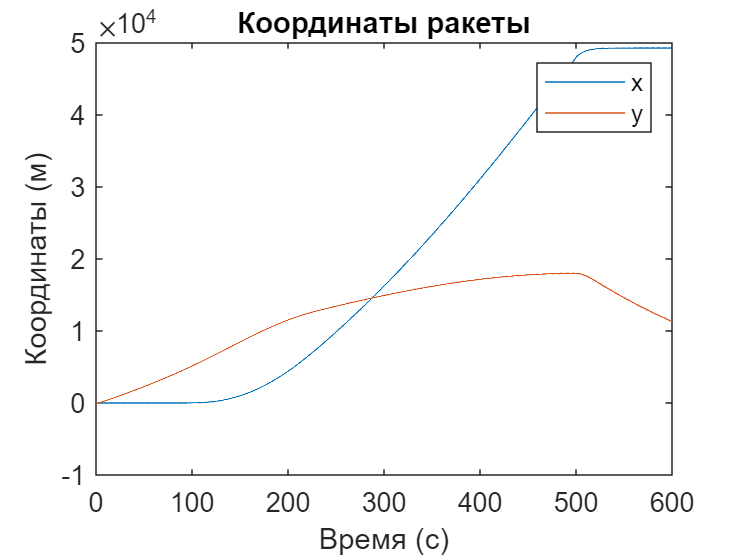


m = u(:, 1);
x = u(:, 2);
y = u(:, 3);
vx = u(:, 4);
vy = u(:, 5);
alpha = u(:, 6);
omega = u(:, 7);

figure;
plot(t, -x, t, y);
xlabel('Время (с)');
ylabel('Координаты (м)');
legend('x', 'y');
title('Координаты ракеты');

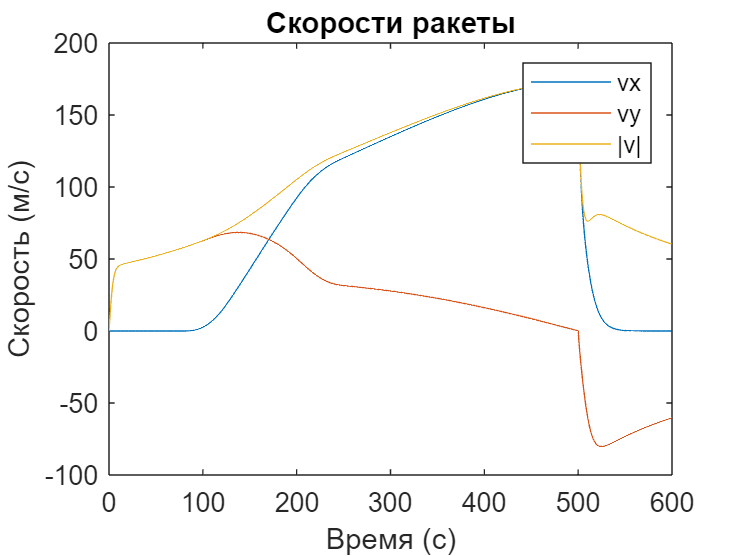


figure;
plot(t, -vx, t, vy, t, sqrt(vx.^2 + vy.^2)); % Magnitude added here
xlabel('Время (с)');
ylabel('Скорость (м/с)');
legend('vx', 'vy', '|v|'); % Legend updated
title('Скорости ракеты');

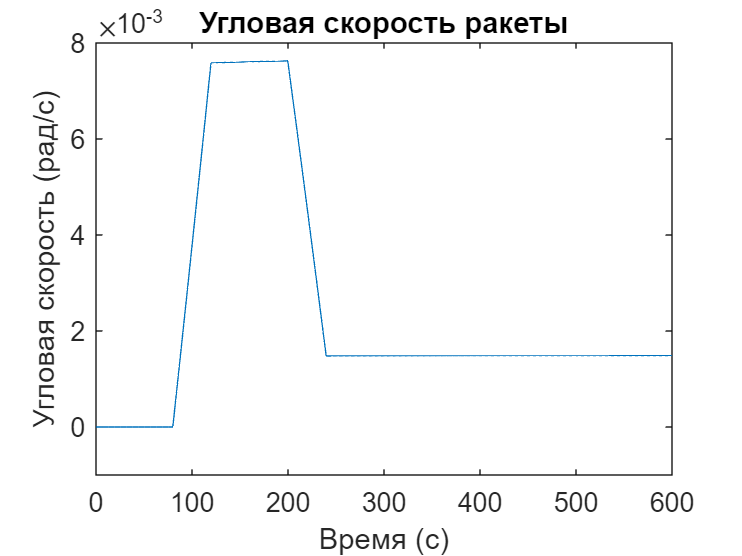


figure;
plot(t, abs(omega));
xlabel('Время (с)');
ylabel('Угловая скорость (рад/с)');
ylim([-0.001 0.008])
title('Угловая скорость ракеты');

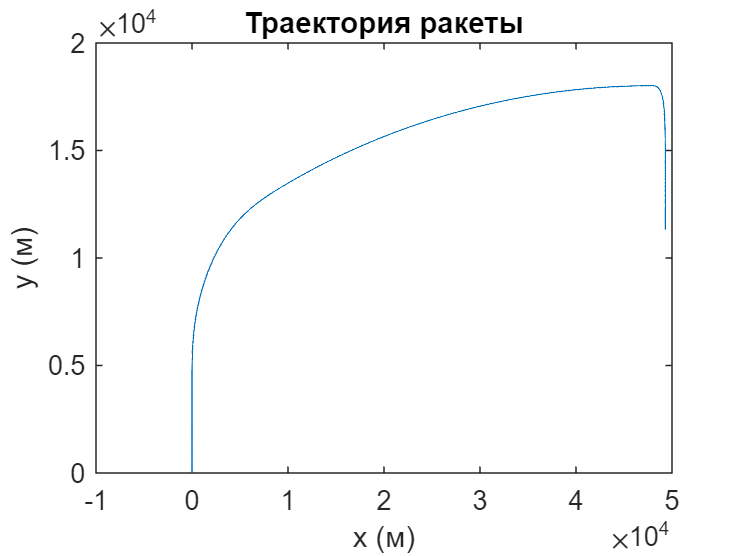


figure;
plot(-x, y);
xlabel('x (м)');
ylabel('y (м)');
title('Траектория ракеты');

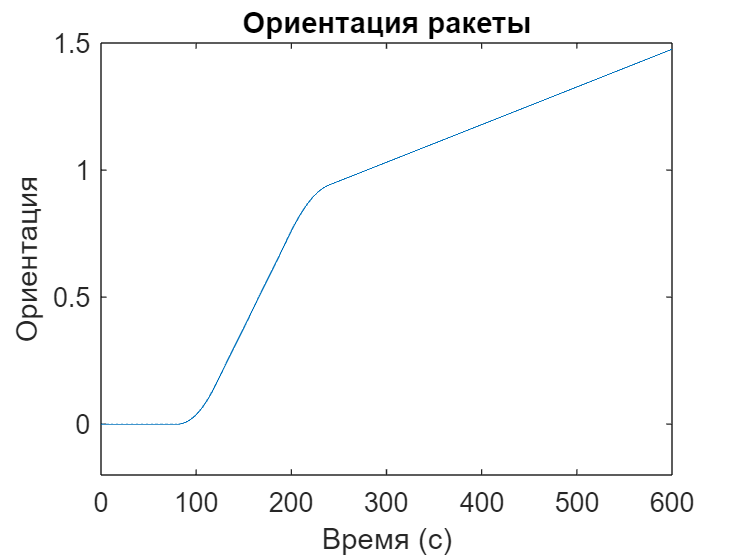


figure;
plot(t, abs(alpha));
xlabel('Время (с)');
ylabel('Ориентация');
ylim([-0.2 1.5])
title('Ориентация ракеты');

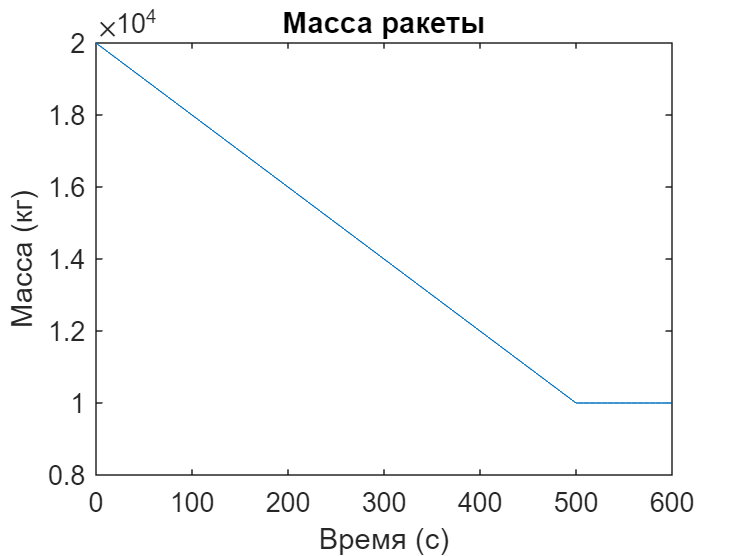


figure;
plot(t, m);
xlabel('Время (с)');
ylabel('Масса (кг)');
ylim([8000 20000])
title('Масса ракеты')